T = 1:400;
N = 10;
tmin = 25;
t0 = 1;
u = binrand(T, N, tmin, t0, 'normal');

x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


% Define the transfer functions
numerator = [1, 0];
denominator = [10, -10];
ts = 0.01;
C = tf(numerator, denominator, ts);

num = [0.1812];
den = [1, -0.8187];
G = tf(num, den, ts);

variance1 = 0.1; % also for 0.01 and 0.001
variance2 = 0.01;
variance3 = 0.001;
noise1 = sqrt(variance1) * randn(size(u));
noise2 = sqrt(variance2) * randn(size(u));
noise3 = sqrt(variance3) * randn(size(u));

Ts = 0.01;                % Sample time of the models
N = length(u); 
timeVector = 0:Ts:(N-1)*Ts;

output1 = lsim((G*C)/(1+(G*C)), u.', timeVector.') + lsim(1/(1+C*G), noise1.', timeVector.');
output2 = lsim((G*C)/(1+(G*C)), u.', timeVector.') + lsim(1/(1+C*G), noise2.', timeVector.');
output3 = lsim((G*C)/(1+(G*C)), u.', timeVector.') + lsim(1/(1+C*G), noise3.', timeVector.');

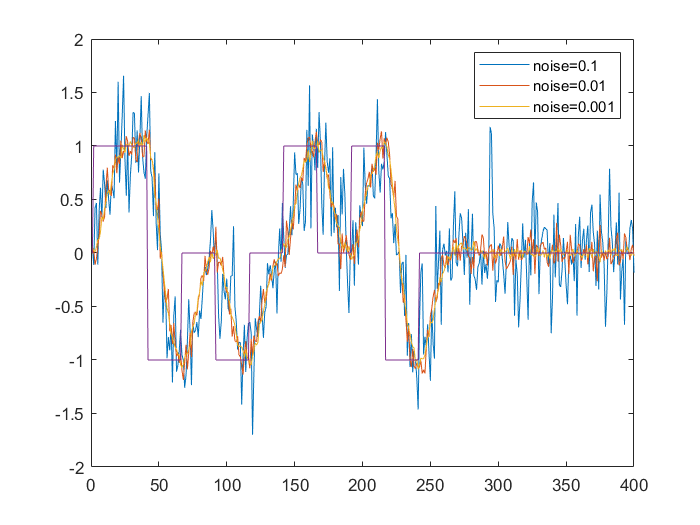

figure;
plot(output1)
hold on
plot(output2)
plot(output3)
plot(u)
legend('noise=0.1','noise=0.01', 'noise=0.001');
hold off

pairs1 = table(u.', output1, 'VariableNames', {'Input', 'Output'});
pairs2 = table(u.', output2, 'VariableNames', {'Input', 'Output'});
pairs3 = table(u.', output3, 'VariableNames', {'Input', 'Output'});

% Define a range of values for na, nb, and nk
% Parameters
na_values = [1, 2, 3 ,4 ];  % List of 'na' values to test
nc_values = [1, 2, 3 ,4];  % List of 'na' values to test
nb_values = [1, 2, 3 ,4 ];  % List of 'nb' values to test
nf_values = [1, 2, 3 ];  % List of 'na' values to test
nd_values = [1, 2, 3 ,4];  % List of 'na' values to test
nk_values = [0, 1, 2, 3 ,4];  % List of 'nk' values to test
best_na = 0;            % Variable to store the best 'na' value
best_nb = 0;            % Variable to store the best 'nb' value
best_nk = 0;            % Variable to store the best 'nk' value
best_nc = 0;            % Variable to store the best 'nk' value
best_nf = 0;            % Variable to store the best 'nk' value
best_nd = 0;            % Variable to store the best 'nk' value
best_val_error = Inf;   % Variable to store the best validation error
best_model = [];        % Variable to store the best model

% BJ with 0.1 noise
best_y_pred = [];  

% Loop over each combination of 'nb', 'nc', 'nd', 'nf', and 'nk' values
for nb = nb_values
    for nc = nc_values
        for nd = nd_values
            for nf = nf_values
                for nk = nk_values
                    % Box-Jenkins Model Identification
                    orders = [0 nb nc nd nf nk];
                    sys = polyest(iddata(output1, u.', 0.01), orders);
                    sys.Ts = 0.01; 
                    y_val_pred = compare(sys, iddata(output1, u.', 0.01)); 
                    val_error = mean((y_val_pred.OutputData - output1).^2);
                    if val_error < best_val_error
                        best_val_error = val_error;
                        best_nb = nb;
                        best_nc = nc;
                        best_nd = nd;
                        best_nf = nf;
                        best_nk = nk;
                        best_model = sys;  % Store the best model
                        best_y_pred = y_val_pred.OutputData;  
                    end
                end
            end
        end
    end
end

% Display the best parameter values and validation error
disp(['Best nb value: ', num2str(best_nb)]);

Best nb value: 4


disp(['Best nc value: ', num2str(best_nc)]);

Best nc value: 1


disp(['Best nd value: ', num2str(best_nd)]);

Best nd value: 4


disp(['Best nf value: ', num2str(best_nf)]);

Best nf value: 3


disp(['Best nk value: ', num2str(best_nk)]);

Best nk value: 3


disp(['Best validation error (MSE): ', num2str(best_val_error)]);

Best validation error (MSE): 0.094756



% Display the best model
disp('Best model:');

Best model:


disp(best_model);

  idpoly with properties:

                 A: 1
                 B: [0 0 0 0.1589 0.0031 -0.3640 0.2358]
                 C: [1 0.5772]
                 D: [1 0.4295 -0.0696 0.0409 0.1472]
                 F: [1 -1.1853 -0.2704 0.4902]
    IntegrateNoise: 0
          Variable: 'z^-1'
           IODelay: 0
         Structure: [1×1 pmodel.polynomial]
     NoiseVariance: 0.0952
            Report: [1×1 idresults.polyest]
        InputDelay: 0
       OutputDelay: 0
                Ts: 0.0100
          TimeUnit: 'seconds'
         InputName: {'u1'}
         InputUnit: {''}
        InputGroup: [1×1 struct]
        OutputName: {'y1'}
        OutputUnit: {''}
       OutputGroup: [1×1 struct]
             Notes: [0×1 string]
          UserData: []
              Name: ''
      SamplingGrid: [1×1 struct]



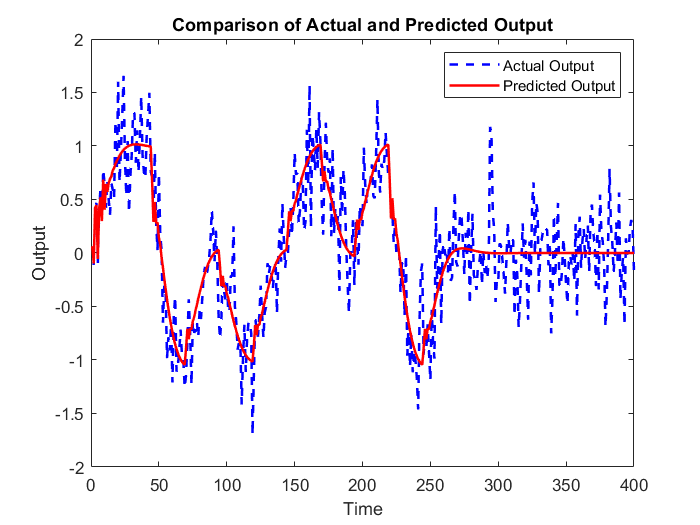

% Plot the actual output and predicted output
figure;
t = 1:length(output1);
plot(t, output1, 'b--', 'LineWidth', 1.5);
hold on;
plot(t, best_y_pred, 'r', 'LineWidth', 1.5);
hold off;
xlabel('Time');
ylabel('Output');
legend('Actual Output', 'Predicted Output');
title('Comparison of Actual and Predicted Output');

best_model

best_model =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)    
  B(z) = 0.1589 z^-3 + 0.003132 z^-4 - 0.364 z^-5 + 0.2358 z^-6     
                                                                    
  C(z) = 1 + 0.5772 z^-1                                            
                                                                    
  D(z) = 1 + 0.4295 z^-1 - 0.06959 z^-2 + 0.04089 z^-3 + 0.1472 z^-4
                                                                    
  F(z) = 1 - 1.185 z^-1 - 0.2704 z^-2 + 0.4902 z^-3                 
                                                                    
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   nb=4   nc=1   nd=4   nf=3   nk=3
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using POLYEST on time domain data.     
Fit to estimation data: 50.15% (prediction focu

% Extract zeros and poles from the estimated ARX model
zeros_est = zero(best_model);
poles_est = pole(best_model);

% Display the zero locations and poles
disp('Estimated Model:');

Estimated Model:


disp('Zeros:');

Zeros:


disp(zeros_est);

  -1.7777 + 0.0000i
   0.8790 + 0.2492i
   0.8790 - 0.2492i



disp('Poles:');

Poles:


disp(poles_est);

   0.0000 + 0.0000i
  -0.6043 + 0.0000i
   0.8948 + 0.1020i
   0.8948 - 0.1020i



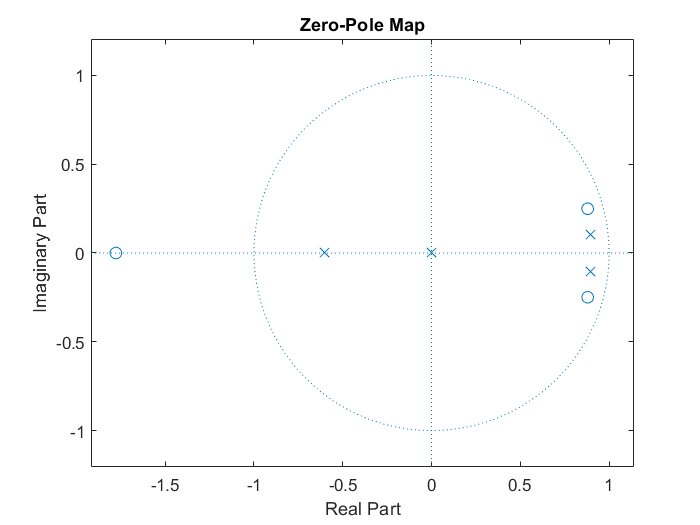


% Plot the zero-pole map
figure;
zplane(zeros_est, poles_est);
title('Zero-Pole Map');

e = u.' - best_y_pred;
corr_eu = corrcoef(e, u.');
corr_eu = corr_eu(1, 2); % Extract the correlation coefficient from the matrix

% Calculate the correlation between e and y
corr_ey = corrcoef(e, best_y_pred);
corr_ey = corr_ey(1, 2); % Extract the correlation coefficient from the matrix

% Display the correlation coefficients
disp('Correlation between e and u:');

Correlation between e and u:


disp(corr_eu);

    0.6104



disp('Correlation between e and y:');

Correlation between e and y:


disp(corr_ey);

   -0.2757



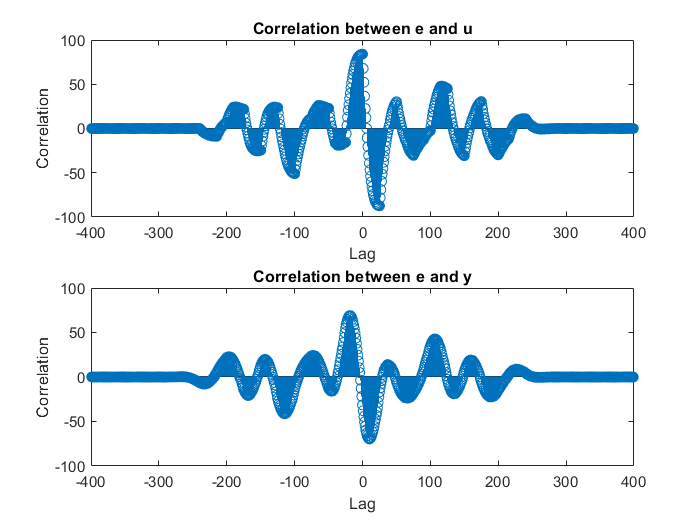


corr_eu = xcorr(e, u.');

% Calculate the correlation between e and y
corr_ey = xcorr(e, best_y_pred);

% Plot the correlation results
lags = -(length(e)-1):(length(e)-1);
figure;
subplot(2, 1, 1);
stem(lags, corr_eu);
title('Correlation between e and u');
xlabel('Lag');
ylabel('Correlation');
subplot(2, 1, 2);
stem(lags, corr_ey);
title('Correlation between e and y');
xlabel('Lag');
ylabel('Correlation');

% ARX with 0.01 noise
best_y_pred = [];  
best_na = 0;            % Variable to store the best 'na' value
best_nb = 0;            % Variable to store the best 'nb' value
best_nk = 0;            % Variable to store the best 'nk' value
best_nc = 0;            % Variable to store the best 'nk' value
best_nf = 0;            % Variable to store the best 'nk' value
best_nd = 0;            % Variable to store the best 'nk' value
best_val_error = Inf;   % Variable to store the best validation error
best_model = [];        % Variable to store the best model
% Loop over each combination of 'nb', 'nc', 'nd', 'nf', and 'nk' values
for nb = nb_values
    for nc = nc_values
        for nd = nd_values
            for nf = nf_values
                for nk = nk_values
                    % Box-Jenkins Model Identification
                    orders = [0 nb nc nd nf nk];
                    sys = polyest(iddata(output2, u.', 0.01), orders);
                    sys.Ts = 0.01; 
                    y_val_pred = compare(sys, iddata(output2, u.', 0.01)); 
                    val_error = mean((y_val_pred.OutputData - output2).^2);
                    if val_error < best_val_error
                        best_val_error = val_error;
                        best_nb = nb;
                        best_nc = nc;
                        best_nd = nd;
                        best_nf = nf;
                        best_nk = nk;
                        best_model = sys;  % Store the best model
                        best_y_pred = y_val_pred.OutputData;  
                    end
                end
            end
        end
    end
end

% Display the best parameter values and validation error
disp(['Best nb value: ', num2str(best_nb)]);

Best nb value: 4


disp(['Best nc value: ', num2str(best_nc)]);

Best nc value: 3


disp(['Best nd value: ', num2str(best_nd)]);

Best nd value: 4


disp(['Best nf value: ', num2str(best_nf)]);

Best nf value: 3


disp(['Best nk value: ', num2str(best_nk)]);

Best nk value: 3


disp(['Best validation error (MSE): ', num2str(best_val_error)]);

Best validation error (MSE): 0.0093907



% Display the best model
disp('Best model:');

Best model:


disp(best_model);

  idpoly with properties:

                 A: 1
                 B: [0 0 0 0.0772 -0.0066 -0.0805 0.0591]
                 C: [1 -1.1918 1.2781 -0.6684]
                 D: [1 -1.2415 1.3167 -0.6736 -0.0095]
                 F: [1 -0.9202 -0.6583 0.6271]
    IntegrateNoise: 0
          Variable: 'z^-1'
           IODelay: 0
         Structure: [1×1 pmodel.polynomial]
     NoiseVariance: 0.0102
            Report: [1×1 idresults.polyest]
        InputDelay: 0
       OutputDelay: 0
                Ts: 0.0100
          TimeUnit: 'seconds'
         InputName: {'u1'}
         InputUnit: {''}
        InputGroup: [1×1 struct]
        OutputName: {'y1'}
        OutputUnit: {''}
       OutputGroup: [1×1 struct]
             Notes: [0×1 string]
          UserData: []
              Name: ''
      SamplingGrid: [1×1 struct]



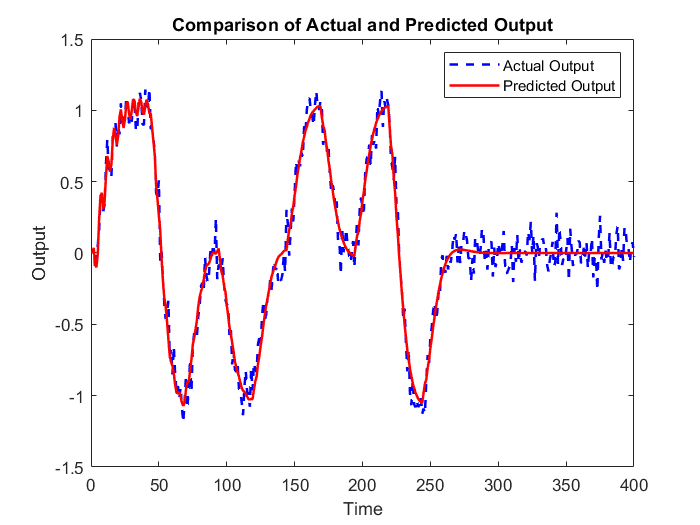

% Plot the actual output and predicted output
figure;
t = 1:length(output2);
plot(t, output2, 'b--', 'LineWidth', 1.5);
hold on;
plot(t, best_y_pred, 'r', 'LineWidth', 1.5);
hold off;
xlabel('Time');
ylabel('Output');
legend('Actual Output', 'Predicted Output');
title('Comparison of Actual and Predicted Output');

best_model

best_model =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)  
  B(z) = 0.0772 z^-3 - 0.006589 z^-4 - 0.08047 z^-5 + 0.05905 z^-6
                                                                  
  C(z) = 1 - 1.192 z^-1 + 1.278 z^-2 - 0.6684 z^-3                
                                                                  
  D(z) = 1 - 1.242 z^-1 + 1.317 z^-2 - 0.6736 z^-3 - 0.00946 z^-4 
                                                                  
  F(z) = 1 - 0.9202 z^-1 - 0.6583 z^-2 + 0.6271 z^-3              
                                                                  
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   nb=4   nc=3   nd=4   nf=3   nk=3
   Number of free coefficients: 14
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using POLYEST on time domain data.     
Fit to estimation data: 82.33% (prediction focus)
FPE: 0.01059, M

% Extract zeros and poles from the estimated ARX model
zeros_est = zero(best_model);
poles_est = pole(best_model);

% Display the zero locations and poles
disp('Estimated Model:');

Estimated Model:


disp('Zeros:');

Zeros:


disp(zeros_est);

  -1.2451 + 0.0000i
   0.6652 + 0.4145i
   0.6652 - 0.4145i



disp('Poles:');

Poles:


disp(poles_est);

   0.0000 + 0.0000i
  -0.8189 + 0.0000i
   0.8696 + 0.0985i
   0.8696 - 0.0985i



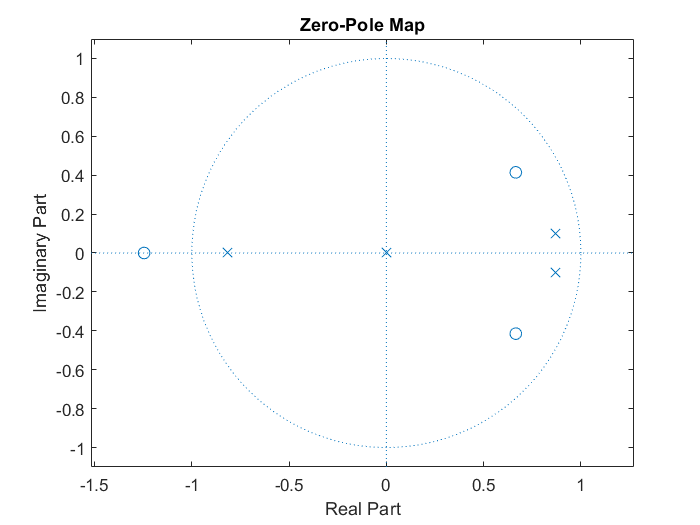


% Plot the zero-pole map
figure;
zplane(zeros_est, poles_est);
title('Zero-Pole Map');

e = u.' - best_y_pred;
corr_eu = corrcoef(e, u.');
corr_eu = corr_eu(1, 2); % Extract the correlation coefficient from the matrix

% Calculate the correlation between e and y
corr_ey = corrcoef(e, best_y_pred);
corr_ey = corr_ey(1, 2); % Extract the correlation coefficient from the matrix

% Display the correlation coefficients
disp('Correlation between e and u:');

Correlation between e and u:


disp(corr_eu);

    0.5891



disp('Correlation between e and y:');

Correlation between e and y:


disp(corr_ey);

   -0.3460



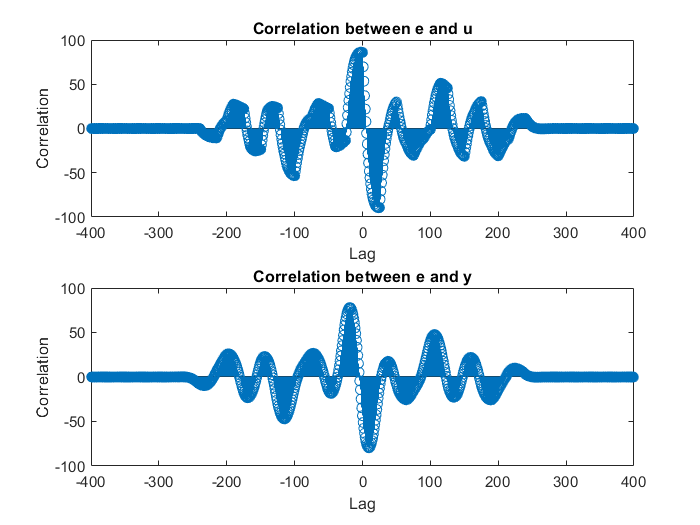


corr_eu = xcorr(e, u.');

% Calculate the correlation between e and y
corr_ey = xcorr(e, best_y_pred);

% Plot the correlation results
lags = -(length(e)-1):(length(e)-1);
figure;
subplot(2, 1, 1);
stem(lags, corr_eu);
title('Correlation between e and u');
xlabel('Lag');
ylabel('Correlation');
subplot(2, 1, 2);
stem(lags, corr_ey);
title('Correlation between e and y');
xlabel('Lag');
ylabel('Correlation');

% ARX with 0.01 noise
best_y_pred = [];  
best_na = 0;            % Variable to store the best 'na' value
best_nb = 0;            % Variable to store the best 'nb' value
best_nk = 0;            % Variable to store the best 'nk' value
best_nc = 0;            % Variable to store the best 'nk' value
best_nf = 0;            % Variable to store the best 'nk' value
best_nd = 0;            % Variable to store the best 'nk' value
best_val_error = Inf;   % Variable to store the best validation error
best_model = [];        % Variable to store the best model
% Loop over each combination of 'nb', 'nc', 'nd', 'nf', and 'nk' values
for nb = nb_values
    for nc = nc_values
        for nd = nd_values
            for nf = nf_values
                for nk = nk_values
                    % Box-Jenkins Model Identification
                    orders = [0 nb nc nd nf nk];
                    sys = polyest(iddata(output3, u.', 0.01), orders);
                    sys.Ts = 0.01; 
                    y_val_pred = compare(sys, iddata(output3, u.', 0.01)); 
                    val_error = mean((y_val_pred.OutputData - output3).^2);
                    if val_error < best_val_error
                        best_val_error = val_error;
                        best_nb = nb;
                        best_nc = nc;
                        best_nd = nd;
                        best_nf = nf;
                        best_nk = nk;
                        best_model = sys;  % Store the best model
                        best_y_pred = y_val_pred.OutputData;  
                    end
                end
            end
        end
    end
end

% Display the best parameter values and validation error
disp(['Best nb value: ', num2str(best_nb)]);

Best nb value: 4


disp(['Best nc value: ', num2str(best_nc)]);

Best nc value: 4


disp(['Best nd value: ', num2str(best_nd)]);

Best nd value: 2


disp(['Best nf value: ', num2str(best_nf)]);

Best nf value: 2


disp(['Best nk value: ', num2str(best_nk)]);

Best nk value: 2


disp(['Best validation error (MSE): ', num2str(best_val_error)]);

Best validation error (MSE): 0.00093898



% Display the best model
disp('Best model:');

Best model:


disp(best_model);

  idpoly with properties:

                 A: 1
                 B: [0 0 0.0593 -0.0794 0.0533 -0.0155]
                 C: [1 -0.9368 1.0468 -0.0542 -0.0037]
                 D: [1 -0.8849 1.0058]
                 F: [1 -1.8028 0.8206]
    IntegrateNoise: 0
          Variable: 'z^-1'
           IODelay: 0
         Structure: [1×1 pmodel.polynomial]
     NoiseVariance: 9.9097e-04
            Report: [1×1 idresults.polyest]
        InputDelay: 0
       OutputDelay: 0
                Ts: 0.0100
          TimeUnit: 'seconds'
         InputName: {'u1'}
         InputUnit: {''}
        InputGroup: [1×1 struct]
        OutputName: {'y1'}
        OutputUnit: {''}
       OutputGroup: [1×1 struct]
             Notes: [0×1 string]
          UserData: []
              Name: ''
      SamplingGrid: [1×1 struct]



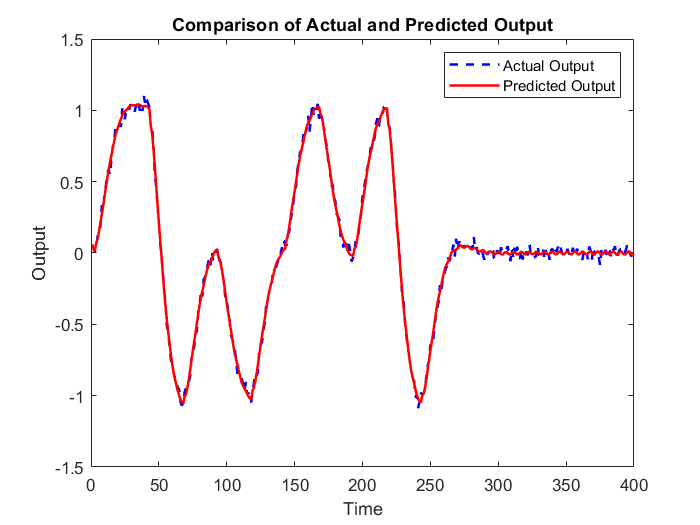

% Plot the actual output and predicted output
figure;
t = 1:length(output3);
plot(t, output3, 'b--', 'LineWidth', 1.5);
hold on;
plot(t, best_y_pred, 'r', 'LineWidth', 1.5);
hold off;
xlabel('Time');
ylabel('Output');
legend('Actual Output', 'Predicted Output');
title('Comparison of Actual and Predicted Output');

best_model

best_model =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)    
  B(z) = 0.05933 z^-2 - 0.07941 z^-3 + 0.05326 z^-4 - 0.01547 z^-5  
                                                                    
  C(z) = 1 - 0.9368 z^-1 + 1.047 z^-2 - 0.05415 z^-3 - 0.003651 z^-4
                                                                    
  D(z) = 1 - 0.8849 z^-1 + 1.006 z^-2                               
                                                                    
  F(z) = 1 - 1.803 z^-1 + 0.8206 z^-2                               
                                                                    
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   nb=4   nc=4   nd=2   nf=2   nk=2
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using POLYEST on time domain data.     
Fit to estimation data: 94.33% (prediction focu

% Extract zeros and poles from the estimated ARX model
zeros_est = zero(best_model);
poles_est = pole(best_model);

% Display the zero locations and poles
disp('Estimated Model:');

Estimated Model:


disp('Zeros:');

Zeros:


disp(zeros_est);

   0.3862 + 0.5580i
   0.3862 - 0.5580i
   0.5661 + 0.0000i



disp('Poles:');

Poles:


disp(poles_est);

   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.9014 + 0.0898i
   0.9014 - 0.0898i



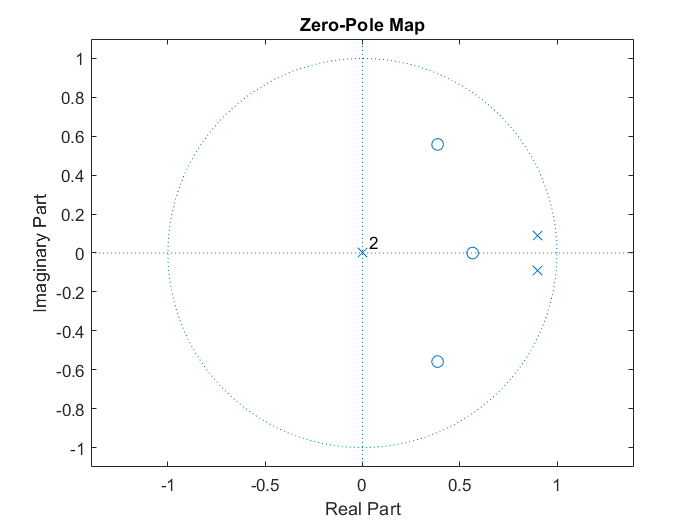


% Plot the zero-pole map
figure;
zplane(zeros_est, poles_est);
title('Zero-Pole Map');

e = u.' - best_y_pred;
corr_eu = corrcoef(e, u.');
corr_eu = corr_eu(1, 2); % Extract the correlation coefficient from the matrix

% Calculate the correlation between e and y
corr_ey = corrcoef(e, best_y_pred);
corr_ey = corr_ey(1, 2); % Extract the correlation coefficient from the matrix

% Display the correlation coefficients
disp('Correlation between e and u:');

Correlation between e and u:


disp(corr_eu);

    0.5976



disp('Correlation between e and y:');

Correlation between e and y:


disp(corr_ey);

   -0.3350



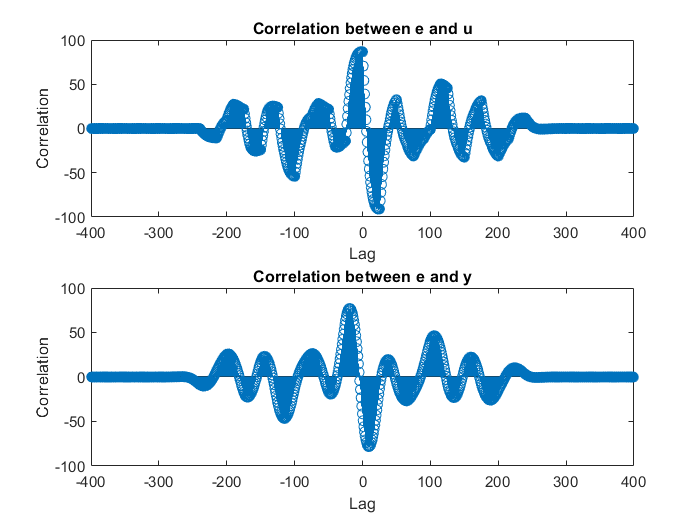


corr_eu = xcorr(e, u.');

% Calculate the correlation between e and y
corr_ey = xcorr(e, best_y_pred);

% Plot the correlation results
lags = -(length(e)-1):(length(e)-1);
figure;
subplot(2, 1, 1);
stem(lags, corr_eu);
title('Correlation between e and u');
xlabel('Lag');
ylabel('Correlation');
subplot(2, 1, 2);
stem(lags, corr_ey);
title('Correlation between e and y');
xlabel('Lag');
ylabel('Correlation');

best_y_pred = [];  
best_na = 0;            % Variable to store the best 'na' value
best_nb = 0;            % Variable to store the best 'nb' value
best_nk = 0;            % Variable to store the best 'nk' value
best_nc = 0;            % Variable to store the best 'nk' value
best_nf = 0;            % Variable to store the best 'nk' value
best_nd = 0;            % Variable to store the best 'nk' value
best_val_error = Inf;   % Variable to store the best validation error
best_model = [];        % Variable to store the best model
% Loop over each combination of 'nb', 'nc', 'nd', 'nf', and 'nk' values
for nb = nb_values
    for nc = nc_values
        for nd = nd_values
                for nk = nk_values
                    % Box-Jenkins Model Identification
                    orders = [0 nb nc nd 1 nk];
                    sys = polyest(iddata(output3, u.', 0.01), orders);
                    sys.Ts = 0.01; 
                    y_val_pred = compare(sys, iddata(output3, u.', 0.01)); 
                    val_error = mean((y_val_pred.OutputData - output3).^2);
                    if val_error < best_val_error
                        best_val_error = val_error;
                        best_nb = nb;
                        best_nc = nc;
                        best_nd = nd;
                        best_nf = nf;
                        best_nk = nk;
                        best_model = sys;  % Store the best model
                        best_y_pred = y_val_pred.OutputData;  
                    end
            end
        end
    end
end

% Display the best parameter values and validation error
disp(['Best nb value: ', num2str(best_nb)]);

Best nb value: 4


disp(['Best nc value: ', num2str(best_nc)]);

Best nc value: 4


disp(['Best nd value: ', num2str(best_nd)]);

Best nd value: 4


disp(['Best nf value: ', num2str(best_nf)]);

Best nf value: 3


disp(['Best nk value: ', num2str(best_nk)]);

Best nk value: 4


disp(['Best validation error (MSE): ', num2str(best_val_error)]);

Best validation error (MSE): 0.0041536



% Display the best model
disp('Best model:');

Best model:


disp(best_model);

  idpoly with properties:

                 A: 1
                 B: [0 0 0 0 0.0760 0.0082 -0.0089 0.0464]
                 C: [1 0.3326 -1.0156 -0.7079 0.3981]
                 D: [1 -0.1510 -1.3764 -0.3426 0.8770]
                 F: [1 -0.8857]
    IntegrateNoise: 0
          Variable: 'z^-1'
           IODelay: 0
         Structure: [1×1 pmodel.polynomial]
     NoiseVariance: 0.0018
            Report: [1×1 idresults.polyest]
        InputDelay: 0
       OutputDelay: 0
                Ts: 0.0100
          TimeUnit: 'seconds'
         InputName: {'u1'}
         InputUnit: {''}
        InputGroup: [1×1 struct]
        OutputName: {'y1'}
        OutputUnit: {''}
       OutputGroup: [1×1 struct]
             Notes: [0×1 string]
          UserData: []
              Name: ''
      SamplingGrid: [1×1 struct]



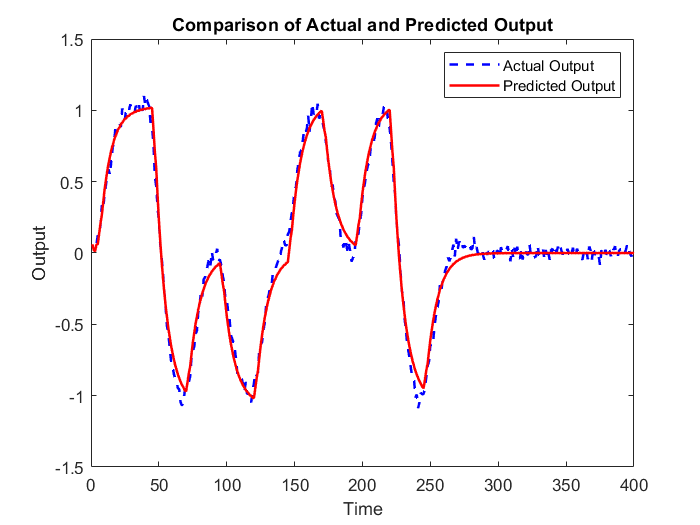

% Plot the actual output and predicted output
figure;
t = 1:length(output3);
plot(t, output3, 'b--', 'LineWidth', 1.5);
hold on;
plot(t, best_y_pred, 'r', 'LineWidth', 1.5);
hold off;
xlabel('Time');
ylabel('Output');
legend('Actual Output', 'Predicted Output');
title('Comparison of Actual and Predicted Output');

best_model

best_model =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)    
  B(z) = 0.07595 z^-4 + 0.008239 z^-5 - 0.008949 z^-6 + 0.04639 z^-7
                                                                    
  C(z) = 1 + 0.3326 z^-1 - 1.016 z^-2 - 0.7079 z^-3 + 0.3981 z^-4   
                                                                    
  D(z) = 1 - 0.151 z^-1 - 1.376 z^-2 - 0.3426 z^-3 + 0.877 z^-4     
                                                                    
  F(z) = 1 - 0.8857 z^-1                                            
                                                                    
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   nb=4   nc=4   nd=4   nf=1   nk=4
   Number of free coefficients: 13
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using POLYEST on time domain data.     
Fit to estimation data: 92.32% (prediction focu

% Extract zeros and poles from the estimated ARX model
zeros_est = zero(best_model);
poles_est = pole(best_model);

% Display the zero locations and poles
disp('Estimated Model:');

Estimated Model:


disp('Zeros:');

Zeros:


disp(zeros_est);

  -0.9343 + 0.0000i
   0.4129 + 0.6952i
   0.4129 - 0.6952i



disp('Poles:');

Poles:


disp(poles_est);

         0
         0
         0
    0.8857



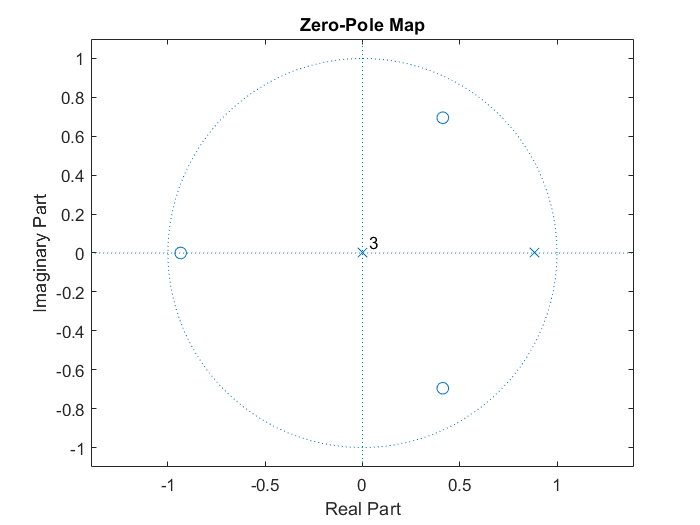


% Plot the zero-pole map
figure;
zplane(zeros_est, poles_est);
title('Zero-Pole Map');